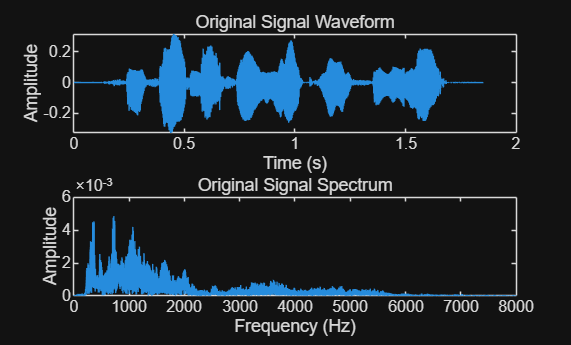

clear; clc; close all;
[y1, fs] = audioread("C:\Users\18237\Desktop\C_01_02(1).wav");
y1 = y1(:)'; 
vocoder_input = y1;


L = length(y1);
t = (0:L-1) / fs; 
f = fs * (0:(L/2)) / L; 

LPF_cut_freq = 50;
[b0, a0] = butter(2, LPF_cut_freq/(fs/2)); 


figure('Name', 'Original Signal');
subplot(2,1,1);
plot(t, y1);
title('Original Signal Waveform');
xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y1_fft = fft(y1);
P1 = abs(Y1_fft/L); P1_single = P1(1:floor(L/2)+1); P1_single(2:end-1) = 2*P1_single(2:end-1);
plot(f, P1_single);
title('Original Signal Spectrum');
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000]);

平均划分频带

N = 4;
pass_band_lower = 200 : (7000-200)/N : 7000-(7000-200)/N;
pass_band_upper = 200+(7000-200)/N : (7000-200)/N : 7000;
center_freq = (pass_band_lower + pass_band_upper) / 2;
disp('平均频率划分结果：');

平均频率划分结果：


disp(table((1:N)', pass_band_lower', pass_band_upper', center_freq', ...
    'VariableNames', {'Band', 'Lower_Hz', 'Upper_Hz', 'Center_Hz'}));

    Band    Lower_Hz    Upper_Hz    Center_Hz
    ____    ________    ________    _________

     1         200        1900        1050   
     2        1900        3600        2750   
     3        3600        5300        4450   
     4        5300        7000        6150   



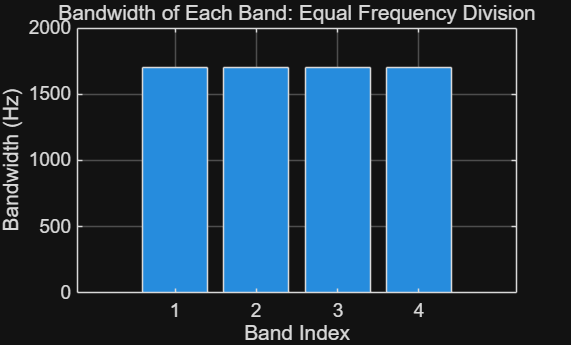

figure('Name', 'Equal Frequency Division Bandwidth');
bar(1:N, pass_band_upper - pass_band_lower);
title('Bandwidth of Each Band: Equal Frequency Division');
xlabel('Band Index');
ylabel('Bandwidth (Hz)');
grid on;

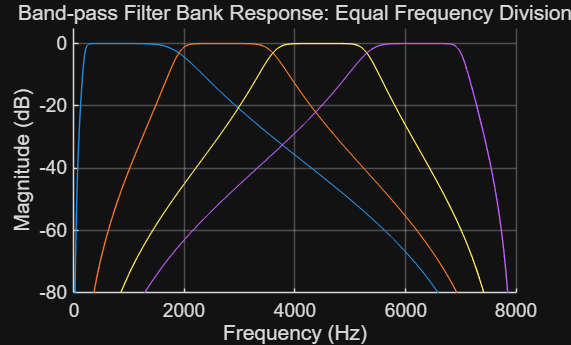

figure('Name', 'Equal Frequency Division Filter Response');
hold on;
for i = 1:N
    Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);
    [B, A] = butter(4, Wn);
    [H, F] = freqz(B, A, 2048, fs);
    plot(F, 20*log10(abs(H) + eps));
end
hold off;
title('Band-pass Filter Bank Response: Equal Frequency Division');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
xlim([0, 8000]);
ylim([-80, 5]);
grid on;

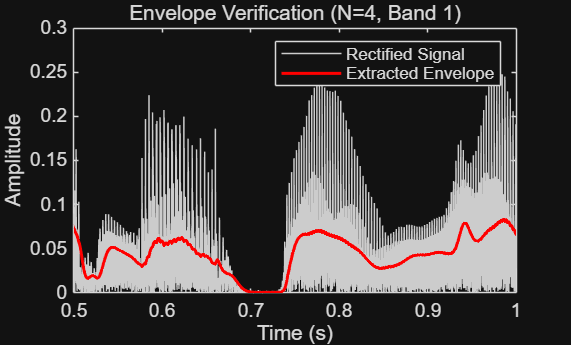


y1_sum = zeros(1, length(y1));
for i = 1:N
    Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);
    [B, A] = butter(4, Wn); 
    y1_band = filter(B, A, vocoder_input);
    y1_band_abs = abs(y1_band);
    y1_envelope = filter(b0, a0, y1_band_abs);
    
    if i == 1 
        figure('Name', sprintf('Envelope Verification N=%d', N));
        plot(t, y1_band_abs, 'Color', [0.8 0.8 0.8]); hold on;
        plot(t, y1_envelope, 'r', 'LineWidth', 1.5); hold off;
        title(sprintf('Envelope Verification (N=%d, Band 1)', N));
        xlabel('Time (s)'); ylabel('Amplitude');
        legend('Rectified Signal', 'Extracted Envelope');
        xlim([0.5, 1.0]); 
    end

    sine_wave = sin(2 * pi * center_freq(i) * t);
    y1_modulated = y1_envelope .* sine_wave;
    y1_sum = y1_sum + y1_modulated;
end

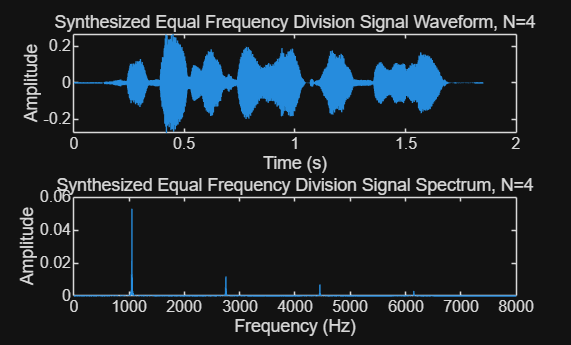



e1 =  sum(vocoder_input.^2);
es = sum(y1_sum.^2);
y1_e = y1_sum * sqrt(e1 / es);


filename = sprintf('Additinal_Task1_equal_N%d.wav', N);
audiowrite(filename,  y1_e, fs);

figure('Name', sprintf('Synthesized N=%d', N));
subplot(2,1,1);
plot(t,  y1_e);
title(sprintf('Synthesized Equal Frequency Division Signal Waveform, N=%d', N));

xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y_fft = fft( y1_e);
P = abs(Y_fft/L); P_single = P(1:floor(L/2)+1); P_single(2:end-1) = 2*P_single(2:end-1);
plot(f, P_single);
title(sprintf('Synthesized Equal Frequency Division Signal Spectrum, N=%d', N));
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000]);

按耳蜗长度划分频带

N = 4;
f_min = 200;
f_max = 7000;

d_min = log10(f_min / 165.4 + 1) / 0.06;
d_max = log10(f_max / 165.4 + 1) / 0.06;

d_edges = linspace(d_min, d_max, N + 1);

pass_band_lower = 165.4 * (10.^(0.06 * d_edges(1:end-1)) - 1);
pass_band_upper = 165.4 * (10.^(0.06 * d_edges(2:end)) - 1);

d_center = (d_edges(1:end-1) + d_edges(2:end)) / 2;
center_freq = 165.4 * (10.^(0.06 * d_center) - 1);
disp('按耳蜗长度划分结果：');

按耳蜗长度划分结果：


disp(table((1:N)', pass_band_lower', pass_band_upper', center_freq', ...
    'VariableNames', {'Band', 'Lower_Hz', 'Upper_Hz', 'Center_Hz'}));

    Band    Lower_Hz    Upper_Hz    Center_Hz
    ____    ________    ________    _________

     1          200      603.53      364.66  
     2       603.53      1452.7      950.04  
     3       1452.7      3239.6      2181.9  
     4       3239.6        7000      4774.1  



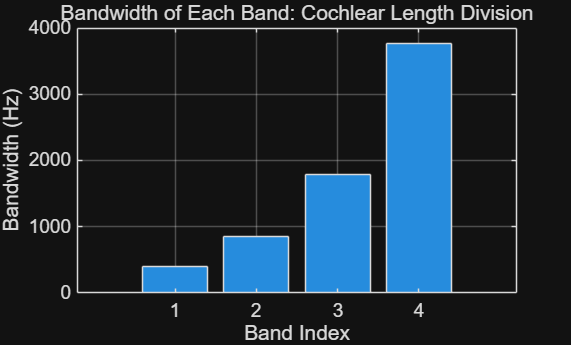

figure('Name', 'Cochlear Length Division Bandwidth');
bar(1:N, pass_band_upper - pass_band_lower);
title('Bandwidth of Each Band: Cochlear Length Division');
xlabel('Band Index');
ylabel('Bandwidth (Hz)');
grid on;

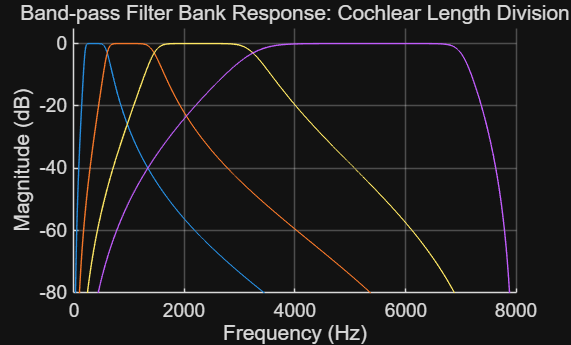

y1_sum = zeros(1, length(y1));
figure('Name', 'Cochlear Length Division Filter Response');
hold on;
for i = 1:N
    Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);
    [B, A] = butter(4, Wn);
    [H, F] = freqz(B, A, 2048, fs);
    plot(F, 20*log10(abs(H) + eps));
end
hold off;
title('Band-pass Filter Bank Response: Cochlear Length Division');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
xlim([0, 8000]);
ylim([-80, 5]);
grid on;

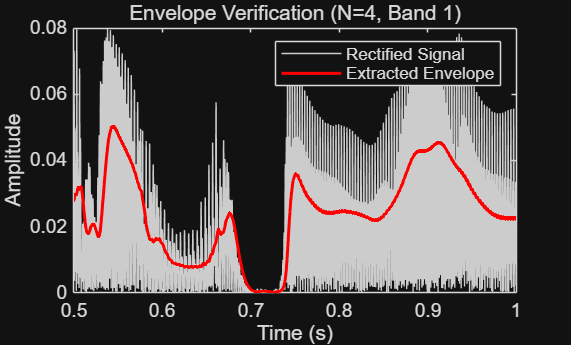

for i = 1:N
    Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);
    [B, A] = butter(4, Wn); 
    y1_band = filter(B, A, vocoder_input);
    y1_band_abs = abs(y1_band);
    y1_envelope = filter(b0, a0, y1_band_abs);
    
    if i == 1 
        figure('Name', sprintf('Envelope Verification N=%d', N));
        plot(t, y1_band_abs, 'Color', [0.8 0.8 0.8]); hold on;
        plot(t, y1_envelope, 'r', 'LineWidth', 1.5); hold off;
        title(sprintf('Envelope Verification (N=%d, Band 1)', N));
        xlabel('Time (s)'); ylabel('Amplitude');
        legend('Rectified Signal', 'Extracted Envelope');
        xlim([0.5, 1.0]); 
    end

    sine_wave = sin(2 * pi * center_freq(i) * t);
    y1_modulated = y1_envelope .* sine_wave;
    y1_sum = y1_sum + y1_modulated;
end

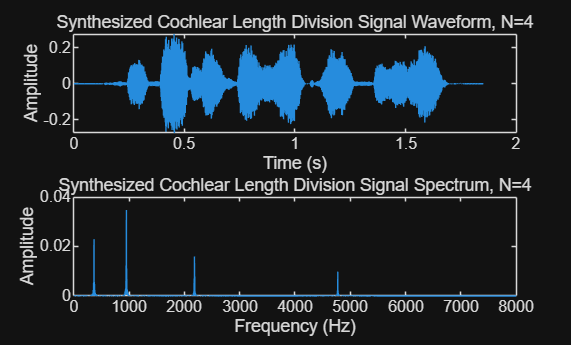


e1 =  sum(vocoder_input.^2);
es = sum(y1_sum.^2);
y1_c = y1_sum * sqrt(e1 / es);




filename = sprintf('Additinal_Task1_cochlea_N%d.wav', N);

audiowrite(filename, y1_c, fs);

figure('Name', sprintf('Synthesized N=%d', N));
subplot(2,1,1);
plot(t, y1_c);
title(sprintf('Synthesized Cochlear Length Division Signal Waveform, N=%d', N));

xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y_fft = fft(y1_c);
P = abs(Y_fft/L); P_single = P(1:floor(L/2)+1); P_single(2:end-1) = 2*P_single(2:end-1);
plot(f, P_single);
title(sprintf('Synthesized Cochlear Length Division Signal Spectrum, N=%d', N));
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000]);